mdl = 'rlCartPoleSimscapeModel';
open_system(mdl)
env = rlPredefinedEnv('CartPoleSimscapeModel-Continuous')

env =   SimulinkEnvWithAgent with properties:

             Model: "rlCartPoleSimscapeModel"
        AgentBlock: "rlCartPoleSimscapeModel/RL Agent"
          ResetFcn: []
    UseFastRestart: 'on'


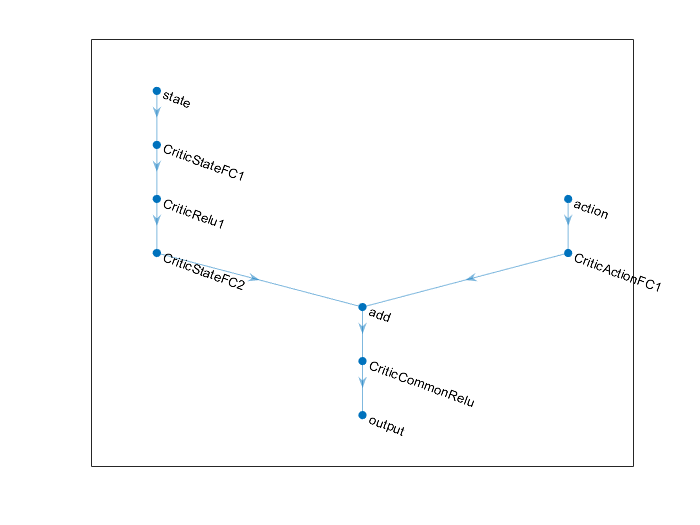

rng(0)
statePath = [
    imageInputLayer([4 1 1],'Normalization','none','Name','state')
    fullyConnectedLayer(24,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(24,'Name','CriticStateFC2')];
actionPath = [
    imageInputLayer([1 1 1],'Normalization','none','Name','action')
    fullyConnectedLayer(24,'Name','CriticActionFC1')];
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','output')];
criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork, actionPath);
criticNetwork = addLayers(criticNetwork, commonPath);    
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');
figure
plot(criticNetwork)

criticOpts = rlRepresentationOptions('LearnRate',0.01,'GradientThreshold',1);
obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);
critic = rlQValueRepresentation(criticNetwork,obsInfo,actInfo,'Observation',{'state'},'Action',{'action'},criticOpts);

Error using rl.representation.rlAbstractRepresentation/validateModelInputDimension (line 529)
Model input sizes must match the dimensions specified in the corresponding observation and action info specifications.

Error in rl.representation.rlQValueRepresentation (line 47)
            validateModelI

agentOpts = rlDQNAgentOptions(...
    'UseDoubleDQN',false, ...    
    'TargetUpdateMethod',"periodic", ...
    'TargetUpdateFrequency',4, ...   
    'ExperienceBufferLength',100000, ...
    'DiscountFactor',0.99, ...
    'MiniBatchSize',256);
agent = rlDQNAgent(critic,agentOpts);
trainOpts = rlTrainingOptions(...
    'MaxEpisodes', 1000, ...
    'MaxStepsPerEpisode', 500, ...
    'Verbose', false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',480); 
plot(env)
trainingStats = train(agent,env,trainOpts)
